# **Interpolare Lagrange**

## 1. Forma clasica


$$\begin{array}{l}
{f\left(x\right)=\;L}_m f+R_m f\\
L_m f\left(x\right)=\sum_{k=0}^m l_k \left(x\right)f\left(x_k \right)\\
l_k \left(x\right)=\prod_{j=0\;;j\;\not= k}^m \frac{x-x_j }{x_k -x_j }\\
R_m f\left(x\right)=\frac{u\left(x\right)}{\left(m+1\right)!}f^{\left(m+1\right)} \left(\xi \right)\\
u\left(x\right)=\prod_{j=0}^m \left(x-x_j \right)\\
L_m f\left(x\right)=\sum_{k=0}^m \prod_{j=0;j\not= k}^m \frac{x-x_j }{x_k -x_j }f\left(x_k \right)
\end{array}$$


function fi = Lagrange(x,y,xi)
    if nargin ~=3 
        error('Illegal number of arguments');
    end
    [mu,nu] = size(xi);
    fi = zeros(mu,nu);
    np1 = length(y);
    for i = 1:np1
        z = ones(mu,nu);
        for j=[1:i-1,i+1:np1]
            z = z.*(xi-x(j))/(x(i) - x(j));
        end
        fi = fi+z*y(i);
    end
end

## 3. Interpolare Lagrange baricentrica


$$\begin{array}{l}
L_m f\left(x\right)=\sum_{k=0}^m l_k \left(x\right)f\left(x_k \right)\\
l_k \left(x\right)=\frac{u\left(x\right)}{\left(x-x_k \right)u^{\prime } \left(x_k \right)}\\
u^{\prime } \left(x_k \right)=\prod_{j=0\;;j\;\not= k}^m x_k -x_j \\
\frac{1}{u^{\prime } \left(x_k \right)}=w_k -\textrm{ponderi}\;\textrm{barincentrie}\Rightarrow w_k =\frac{1}{\prod_{j=0;j\not= m}^m x_k -x_j }\\
L_m f\left(x\right)=\sum_{k=0}^m \frac{u\left(x\right)w_k }{x-x_k }f\left(x_k \right)=u\left(x\right)\sum_{k=0}^m \frac{w_k }{x-x_k }f\left(x_k \right)=\;\frac{u\left(x\right)\sum_{k=0}^m \frac{w_k }{x-x_k }f\left(x_k \right)}{u\left(x\right)\;\sum_{k=0}^m \frac{w_k }{x-x_k }}
\end{array}$$


Tema facultativa: Interporale Lagrange fara for-uri, ponderi baricentrice fara foruri

function ff=barycentricInterpolation(x,y,xx,c)
    %BARYCENTRICINTERPOLATION - barycentric Lagrange interpolation
    %call ff=barycentricInterpolation(x,y,xx,c)
    %x - nodes
    %y - function values
    %xx - interpolation points
    %c - barycentric weights
    %ff - values of interpolation polynomial
    n=length(x)-1;
    numer = zeros(size(xx));
    denom = zeros(size(xx));
    exact = zeros(size(xx));
    for j=1:n+1
    xdiff = xx-x(j);
    temp = c(j)./xdiff;
    numer = numer+temp*y(j);
    denom = denom+temp;
    exact(xdiff==0) = j;
    end
    ff = numer ./ denom;
    jj = find(exact);
    ff(jj) = y(exact(jj));
end

function c = barycentricweigths( x )
    %BARYCENTRICWEIGHTS - compute barycentric weights(coefficient)
    %call c = barycentricweigths( x )
    %x - nodes
    %c - weights
    n=length(x)-1;
    c=ones(1,n+1);
    for j=1:n+1
    c(j)=prod(x(j)-x([1:j-1,j+1:n+1]));
    end
    c=1./c;
end

function ff=ChebLagrange2(y,xx,a,b)
    %CHEBLAGRANGE - Lagrange interpolation for Chebyshev #2 points- barycentric
    %call ff=ChebLagrange(y,xx,a,b)
    %y - function values;
    %xx - evaluation points
    %a,b - interval
    %ff - values of Lagrange interpolation polynomial
    n = length(y)-1;
    if nargin==2
        a=-1; b=1;
    end
    c = [1/2; ones(n-1,1); 1/2].*(-1).^((0:n)');
    x = sort(cos((0:n)'*pi/n))*(b-a)/2+(a+b)/2;
    ff=barycentricInterpolation(x,y,xx,c);
end

function ff=ChebLagrange1(y,xx,a,b)
%CHEBLAGRANGE1 - Lagrange interpolation for Chebyshev #1 points- barycentric
%call ff=ChebLagrangek1(y,xx,a,b)
%y - function values;
%xx - evaluation points
%a,b - interval
%ff - values of Lagrange interpolation polynomial

n = length(y)-1;
if nargin==2
    a=-1; b=1;
end
c = sin((2*(0:n)'+1)*pi/(2*n+2)).*(-1).^((0:n)');
x = sort(cos((2*(0:n)'+1)*pi/(2*n+2))*(b-a)/2+(a+b)/2);
ff=barycentricInterpolation(x,y,xx,c);
end

## 4. Probleme

### Problema 1

    Interpolare Lagrange

### Problema 2

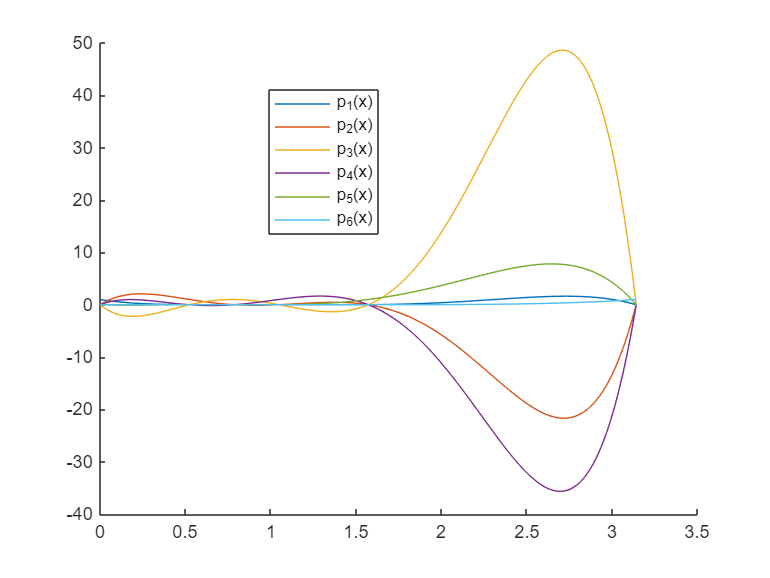

nod = [0, pi/6, pi/4, pi/3, pi/2, pi];
syms x;
np1 = numel(nod);

hold on;
labels = strings(1, np1);

for i = 1:np1
    z = 1;
    for j = setdiff(1:np1, i)
        z = z * (x - nod(j)) / (nod(i) - nod(j));
    end
    vals = linspace(0, pi, 1000);
    plot(vals, double(subs(z, x, vals)));
    labels(i) = sprintf('p_%d(x)', i);
end

legend(labels, 'Location', 'best');
hold off;

### Problema 3 si 4

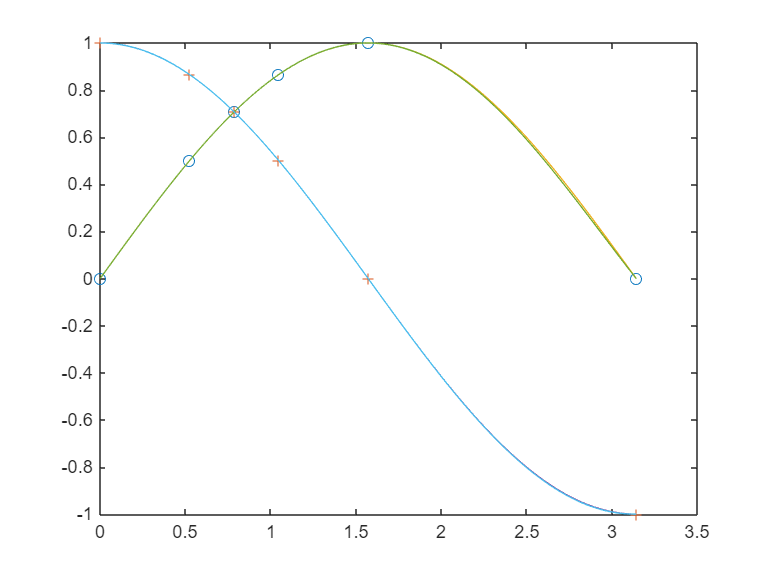

x = [0,pi/6,pi/4,pi/3,pi/2,pi];
y_sin = [0,1/2,sqrt(2)/2,sqrt(3)/2,1,0];
y_cos = [1,sqrt(3)/2,sqrt(2)/2,1/2,0,-1];
t=linspace(0,pi,100);
P_sin = Lagrange(x,y_sin,t);
P_cos = Lagrange(x,y_cos,t);
plot(x, y_sin, 'o', x, y_cos, '+', t, sin(t),t,cos(t),t,P_sin,t,P_cos);

### Problema 5

    Implementare cu puncte Cebisev

## 5. Probleme practice

### Problema 1

x = 1900:10:2010

x =         1900        1910        1920        1930        1940        1950        1960        1970        1980        1990        2000        2010


y=[75995,91972,105711,123203,131669,150697,179323,203212,226505,249633,281422,308786]

y =        75995       91972      105711      123203      131669      150697      179323      203212      226505      249633      281422      308786


format long
P1 = Lagrange(x,y,1975)

P1 =      2.143643887577056e+05


P2 = Lagrange(x,y,2018)

P2 =     -6.643068132291096e+05


### Problema 2

f = @(x) exp(x.^2-1);
x=[1,1.1,1.2,1.3,1.4];
y=f(x);
P = Lagrange(x,y,1.25)

P =    1.754957328862147


### Problema 3

y=10:0.1:11;
x=y.*y;
P = Lagrange(x,y,115)

P =   10.723805294763606


abs(P-sqrt(115))

ans =      1.776356839400250e-15


### Problema 4

#### Contraexemplul lui Runge

Noduri echidistante

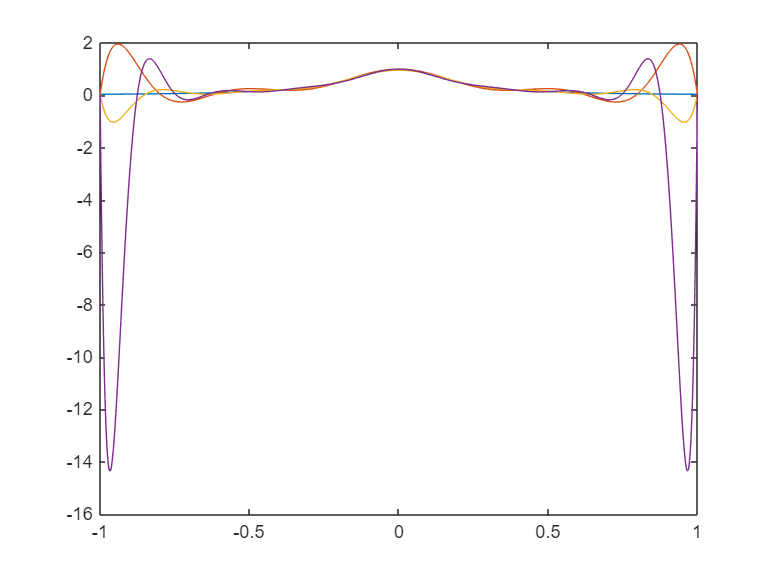

f = @(x) 1./(1+25*x.^2);
tg = linspace(-1,1,3000)';
yg = f(tg);
L = zeros(length(yg),3);
k=0;
for m = [10,13,16]
    xn = linspace(-1,1,m+1);
    yn = f(xn);
    k=k+1;
    c = barycentricweigths(xn);
    L(:,k) = barycentricInterpolation(xn,yn,tg,c);
end
plot(tg,[yg,L])

Cebisev speta #1

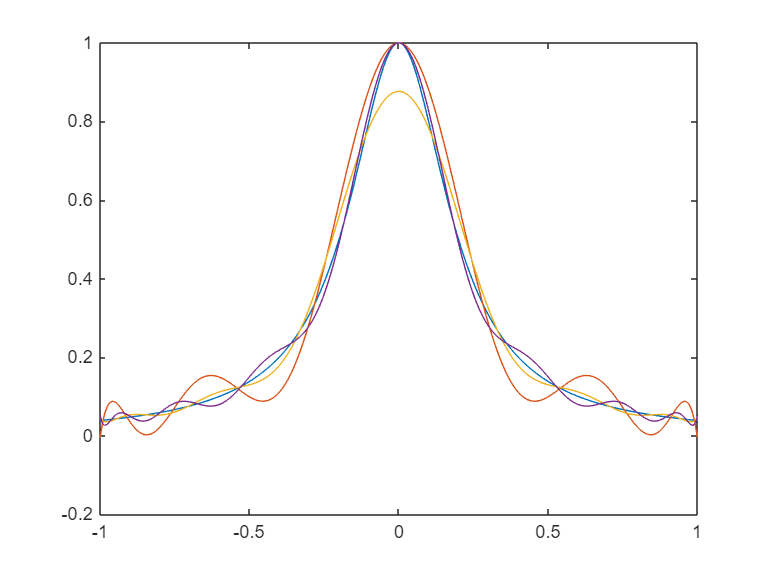

f = @(x) 1./(1+25*x.^2);
tg = linspace(-1,1,3000)';
yg = f(tg);
L = zeros(length(yg),3);
k=0;
for m = [10,13,16]
    xn = sort(cos((2*(0:m)'+1)*pi/(2*m+2)));
    yn = f(xn);
    k=k+1;
    L(:,k) = ChebLagrange1(yn,tg);
end
plot(tg,[yg,L])

Cebisev speta #2

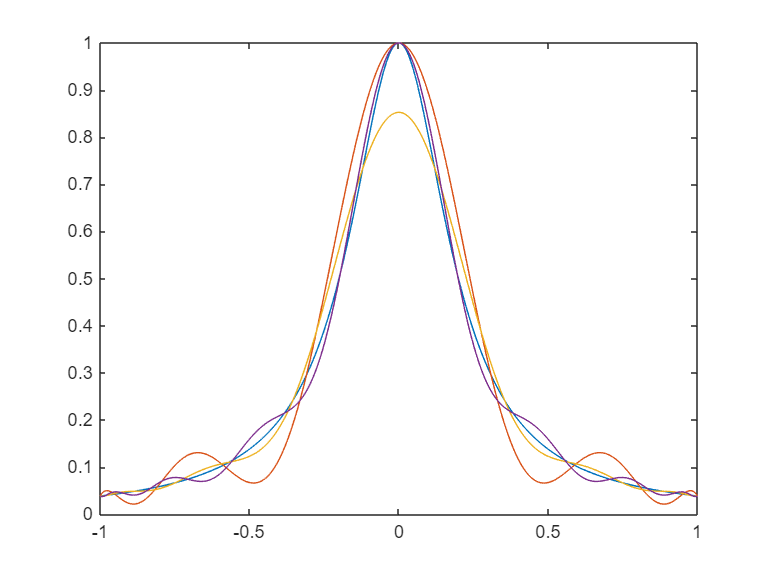

f = @(x) 1./(1+25*x.^2);
tg = linspace(-1,1,3000)';
yg = f(tg);
L = zeros(length(yg),3);
k=0;
for m = [10,13,16]
    xn = sort(cos((0:m)'*pi/m));
    yn = f(xn);
    k=k+1;
    L(:,k) = ChebLagrange2(yn,tg);
end
plot(tg,[yg,L])

#### Contraexemplul lui Bernstein

Noduri echidistante

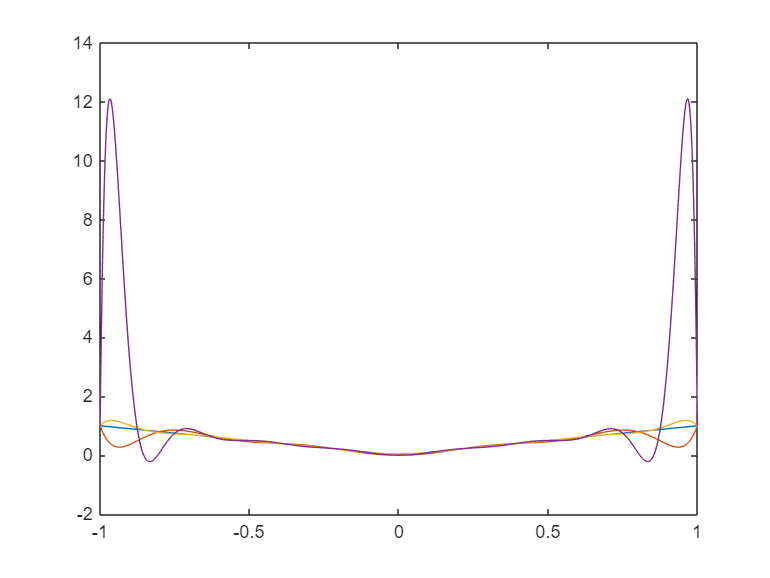

f = @(x) abs(x);
tg = linspace(-1,1,3000)';
yg = f(tg);
L = zeros(length(yg),3);
k=0;
for m = [10,13,16]
    xn = linspace(-1,1,m+1);
    yn = f(xn);
    k=k+1;
    c = barycentricweigths(xn);
    L(:,k) = barycentricInterpolation(xn,yn,tg,c);
end
plot(tg,[yg,L])

Cebisev speta #1

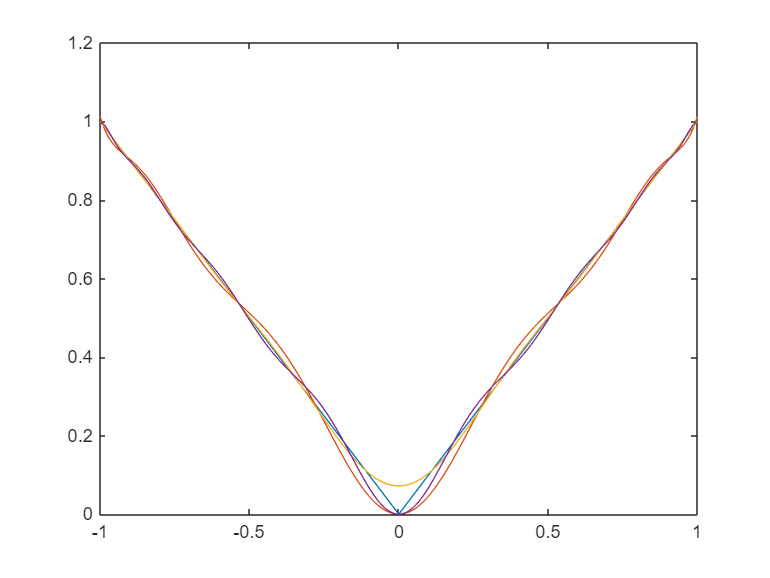

f = @(x) abs(x);
tg = linspace(-1,1,3000)';
yg = f(tg);
L = zeros(length(yg),3);
k=0;
for m = [10,13,16]
    xn = sort(cos((2*(0:m)'+1)*pi/(2*m+2)));
    yn = f(xn);
    k=k+1;
    L(:,k) = ChebLagrange1(yn,tg);
end
plot(tg,[yg,L])

Cebisev speta #2

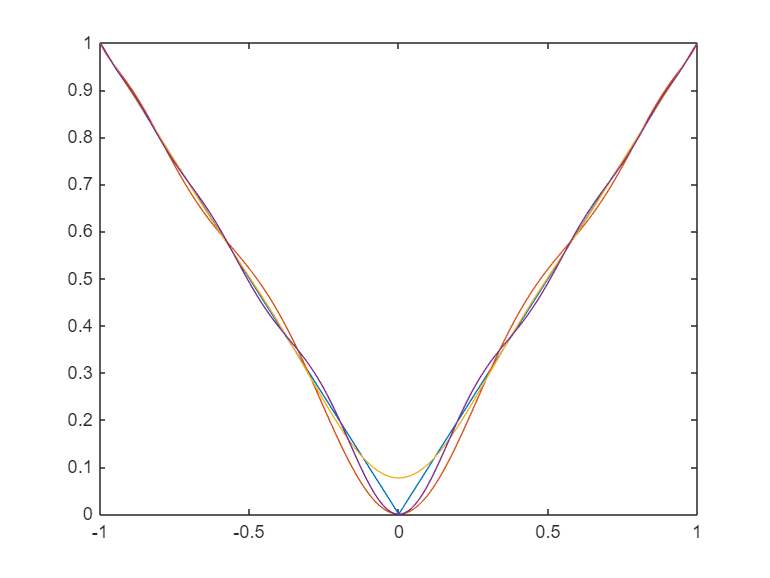

f = @(x) abs(x);
tg = linspace(-1,1,3000)';
yg = f(tg);
L = zeros(length(yg),3);
k=0;
for m = [10,13,16]
    xn = sort(cos((0:m)'*pi/m));
    yn = f(xn);
    k=k+1;
    L(:,k) = ChebLagrange2(yn,tg);
end
plot(tg,[yg,L])

### Problema 5

x = [0,pi/6,pi/4,pi/3,pi/2];
y_sin = [0,1/2,sqrt(2)/2,sqrt(3)/2,1];
y_cos = [1,sqrt(3)/2,sqrt(2)/2,1/2,0];
P_sin=Lagrange(x,y_sin,pi/36)

P_sin =    0.086913410889062


P_cos=Lagrange(x,y_cos,pi/36)

P_cos =    0.996386195987906


abs(cos(pi/36) - P_cos)

ans =      1.914978961601310e-04


abs(sin(pi/36) - P_sin)

ans =      2.423318585964285e-04
